Before using this: 

consider making a names list file

split data samples so we have test and training sets

Start fresh, and load all the data

If we have to manipulate or fix up every data set, we'll do that in this loop too

Transform data sets into usable massive vectors while mashing vectors into covariance matrix

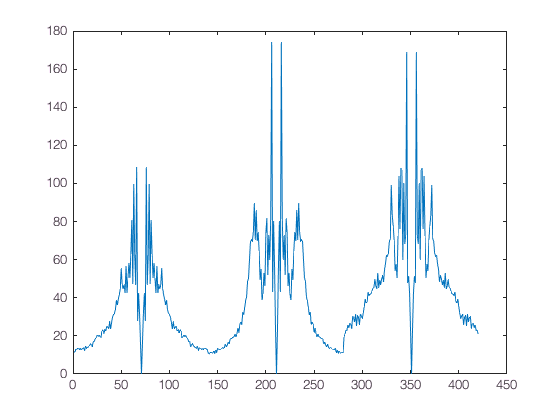

clear all
load allData.mat
dataMatrix = abs(dataMatrix);
nClasses = length(testList);
testMatrix = abs(testMatrix);
%Find the average and take it out
meanGait = mean(dataMatrix,2);
plot(abs(meanGait));

dataMatrix = dataMatrix-meanGait;
testMatrix = testMatrix-meanGait;

Eigenstuff time. We have the vectors matrix, and will pull out the eigen vectors, eigen values, and more eigen vectors I think. U is the matrix of eigenvectors.

Then, make a matrix of coefficients.

[U,S,V] = svd(dataMatrix,'econ');
U = U(:,1:nClasses-1);
coeffMatrix = U'*dataMatrix;

classes =  reshape(coeffMatrix, size(coeffMatrix,1), 4, nClasses);
classes =  classes - mean(classes, 2);
Sc = zeros(size(classes,1));
for i=1:nClasses
    Sc = Sc + classes(:,:,i)*classes(:,:,i)';
end

[V, D] = eig(coeffMatrix*coeffMatrix', Sc);
V = V(:,2:end);
fisherMatrix = V'*coeffMatrix; 

sizeN = length(trainList);
sizeT = length(testList);

A good idea to plot one eigenvector to see if it makes sense

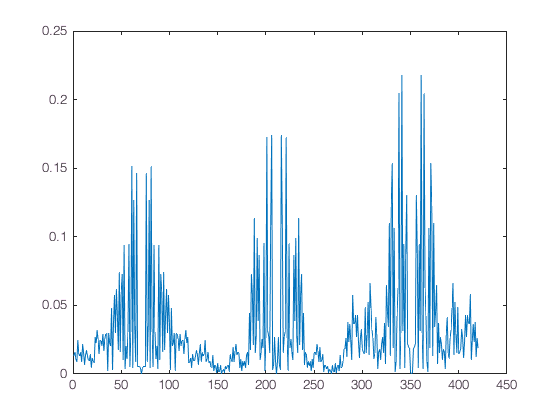

eigenVictim = U(:,1);
hold off; clf;
plot(abs(eigenVictim));

Test a data

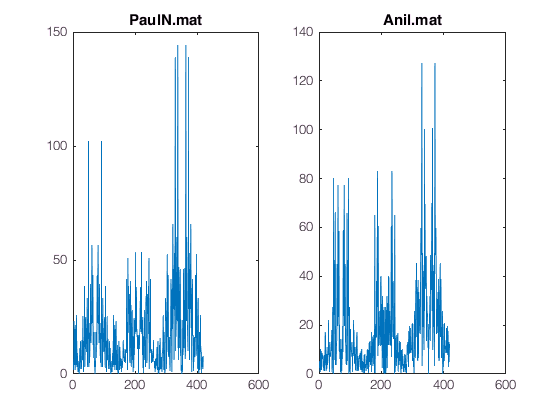

pick = 21;
testGait = testMatrix(:,pick);
testAnswer = testList(pick);
testCoeff = V'*U'*testGait;

% find closest match index for just the one gait
differences = zeros(1,sizeN);
for i = 1:sizeN
    differences(i) = norm(fisherMatrix(:,i)-testCoeff);
end
[minComparison, indexGuessed] = min(differences);
subplot(1,2,1)
plot(abs(testGait));
title(testAnswer)
subplot(1,2,2)
plot(abs(dataMatrix(:,indexGuessed)));
title(trainList(indexGuessed));

amirite = zeros(1,sizeT);
for pick = 1:sizeT
    differences = zeros(1,sizeN);
    testGait = testMatrix(:,pick);
    testAnswer = testList(pick);
    testCoeff = V'*U'*testGait;
    for i = 1:sizeN
        differences(i) = norm(fisherMatrix(:,i)-testCoeff);
    end
    [minComparison, indexGuessed] = min(differences);
    amirite(pick) = isequal(testList(pick),trainList(indexGuessed));
end
mean(amirite)

ans = 0.9630

amirite

amirite =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1
